format longg
disp("Problem 5.3")

Problem 5.3


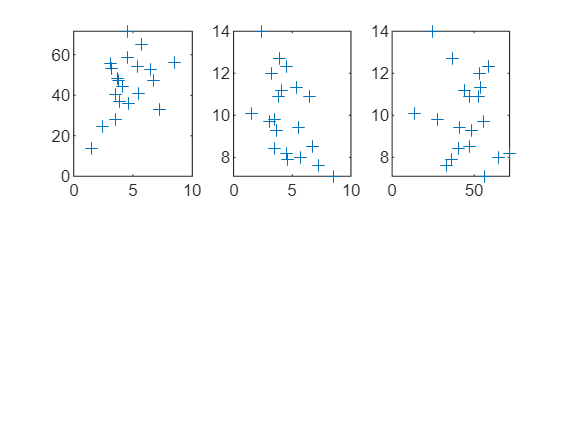

data = [
    3.7 48.5 9.3
    5.7 65.1 8.0
    3.8 47.2 10.9
    3.2 53.2 12.0
    3.1 55.5 9.7
    4.6 36.1 7.9
    2.4 24.8 14.0
    7.2 33.1 7.6
    6.7 47.4 8.5
    5.4 54.1 11.3
    3.9 36.9 12.7
    4.5 58.8 12.3
    3.5 27.8 9.8
    3.5 40.2 8.4
    1.5 13.5 10.1
    8.5 56.4 7.1
    4.5 71.6 8.2
    6.5 52.8 10.9
    4.1 44.1 11.2
    5.5 40.9 9.4
];

cove = cov(data);
[eigvec, eigval] = eig(cove);

subplot(2, 3, 1);
plot(data(:, 1), data(:, 2), '+');
subplot(2, 3, 2);
plot(data(:, 1), data(:, 3), '+');
subplot(2, 3, 3);
plot(data(:, 2), data(:, 3), '+');

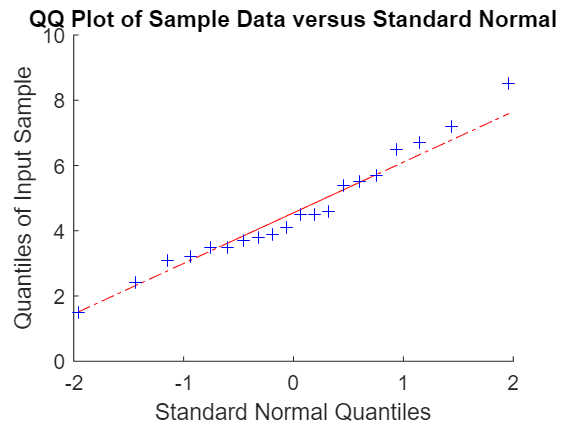


figure
qqplot(data(:, 1));

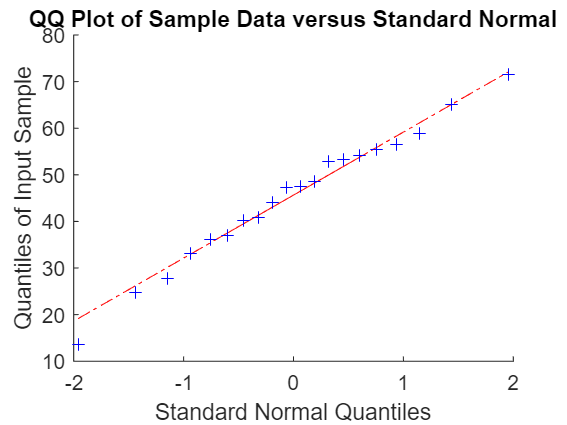

figure
qqplot(data(:, 2));

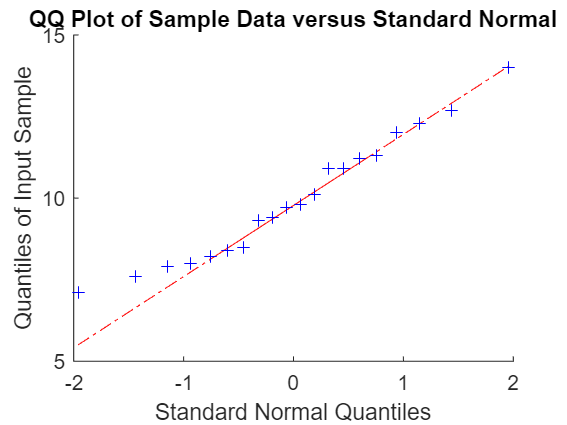

figure
qqplot(data(:, 3));

clf reset;
%%
disp("Problem 5.7")

Problem 5.7


sweat  = [
    3.7 48.5 9.3
    5.7 65.1 8.0
    3.8 47.2 10.9
    3.2 53.2 12.0
    3.1 55.5 9.7
    4.6 36.1 7.9
    2.4 24.8 14.0
    7.2 33.1 7.6
    6.7 47.4 8.5
    5.4 54.1 11.3
    3.9 36.9 12.7
    4.5 58.8 12.3
    3.5 27.8 9.8
    3.5 40.2 8.4
    1.5 13.5 10.1
    8.5 56.4 7.1
    4.5 71.6 8.2
    6.5 52.8 10.9
    4.1 44.1 11.2
    5.5 40.9 9.4
];

avg = mean(sweat);
A1 = avg(1, 1);
A2 = avg(1, 2);
A3 = avg(1, 3);
S1 = sum((sweat(:, 1) - A1)' * (sweat(:, 1) - A1)) / 19;
S2 = sum((sweat(:, 2) - A1)' * (sweat(:, 2) - A2)) / 19;
S3 = sum((sweat(:, 3) - A1)' * (sweat(:, 3) - A3)) / 19;
% S12 = sum((sweat(:, 1) - A1)' * (sweat(:, 1) - A2)) / 10;
%S3 = [S1 S12; S12 S2];
%S = inv(S3); %S4 = S3 ^-1;
%T = 11 * A' * S * A;
a = 0.025;
n = 20;
F = 3.20;
b = 19 * 3 / 17;
T = 9.74;
b1 = [A1 - sqrt(b * F) * sqrt(S1 / 20), A1 + sqrt(b * F) * sqrt(S1 / 20)];
b2 = [A2 - sqrt(b * F) * sqrt(S2 / 20), A2 + sqrt(b * F) * sqrt(S2 / 20)];
b3 = [A3 - sqrt(b * F) * sqrt(S3 / 20), A3 + sqrt(b * F) * sqrt(S3 / 20)];
b = [b1; b2; b3];
disp(b);

          3.33324788348977          5.84675211651023
          35.0471930489985          55.7528069510015
          8.56996173360517          11.3600382663948




t19 = 2.8609;
c1 = [A1 - t19 * sqrt(S1 / 20), A1 + t19 * sqrt(S1 / 20)];
c2 = [A2 - t19 * sqrt(S2 / 20), A2 + t19 * sqrt(S2 / 20)];
c3 = [A3 - t19 * sqrt(S3 / 20), A3 + t19 * sqrt(S3 / 20)];
c = [c1; c2; c3];    
disp(c);

          3.49234882478206          5.68765117521794
          36.3578264740652          54.4421735259347
          8.74656927490656          11.1834307250934



clf reset;
%% 6.4
disp("Problem 6.4")

Problem 6.4


X1 = [6, 6, 18, 8, 11, 34, 28, 71, 43, 33, 20];
Y1 = [27, 23, 64, 44, 30, 75, 26, 124, 54, 30, 14];
X2 = [25, 28, 36, 35, 15, 44, 42, 54, 34, 29, 39];
Y2 = [15, 13, 22, 29, 31, 64, 30, 64, 56, 20, 21];

Z1 = log(X1');
Z2 = log(X2');
Z3 = log(Y1');
Z4 = log(Y2');

D1 = Z1 - Z3;
D2 = Z2 - Z4;

A1 = mean(D1);
A2 = mean(D2);
A = [A1; A2];
disp(A);

        -0.715890343863717
         0.137833076254689




S1 = sum((D1 - A1)' * (D1 - A1)) / 10;
S2 = sum((D2 - A2)' * (D2 - A2)) / 10;
S12 = sum((D1 - A1)' * (D2 - A2)) / 10;

S3 = [S1, S12; S12, S2];
S = inv(S3); % S4 = S3^-1
T = 11 * A' * S * A;

b1 = [A1 - sqrt(9.47) * sqrt(S1 / 11), A1 + sqrt(9.47) * sqrt(S1 / 11)];
b2 = [A2 - sqrt(9.47) * sqrt(S2 / 11), A2 + sqrt(9.47) * sqrt(S2 / 11)];
b = [b1; b2];
disp(b);

         -1.37738862033585       -0.0543920673915873
        -0.325931630463351         0.601597782972729




c1 = [A1 - 2.228 * sqrt(S1 / 11), A1 + 2.228 * sqrt(S1 / 11)];
c2 = [A2 - 2.228 * sqrt(S2 / 11), A2 + 2.228 * sqrt(S2 / 11)];
c = [c1; c2];
disp(c);

         -1.19481689442528        -0.236963793302158
         -0.19793383223252         0.473599984741897



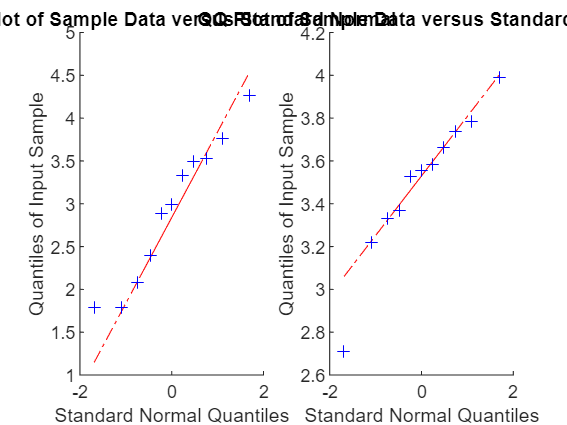


subplot(1, 2, 1);
qqplot(Z1);
subplot(1, 2, 2);
qqplot(Z2);